# MatNWB Optical Physiology Tutorial

## Introduction

In this tutorial, we will create fake data for a hypothetical optical physiology experiment with a freely moving animal. The types of data we will convert are:

- Subject (species, strain, age, etc.)

- Animal position

- Trials

- Acquired two-photon images

- Image segmentation (ROIs)

- Fluorescence and dF/F response

## Installing MatNWB

Use the code below within the brackets to install MatNWB from source. MatNWB works by automatically creating API classes based on the schema. Use `generateCore()` to generate these classes.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd matnwb
addpath(genpath(pwd));
generateCore();
%}

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new `NWBFile` object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...

nwb =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                        file_create_date: []
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
                          general_experiment_description: []
                                    general_experimenter: 'My Name'
                             general_extracellular_ephys: [0×1 types.untyped.Set]
                  general_extracellular_ephys_electrodes: []
                                     general_institution: 'University of My Institution'
                         

    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

subject =   Subject with properties:

              age: 'P90D'
    date_of_birth: []
      description: 'mouse 5'
         genotype: []
              sex: 'M'
          species: 'Mus musculus'
           strain: []
       subject_id: '001'
           weight: []


### Subject information

Create a `Subject` object to store information about the experimental subject, such as age, species, genotype, sex, and a freeform description. Then set `nwb.general_subject` to the `Subject` object.

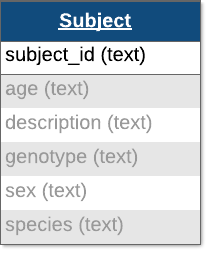

Each of these fields is free-form, so any values will be valid, but here are our recommendations:

- For `age`, we recommend using the [ISO 8601 Duration format](https://en.wikipedia.org/wiki/ISO_8601#Durations)

- For `species`, we recommend using the formal latin binomal name (e.g. mouse -> *Mus musculus*, human -> *Homo sapiens*)

- For `sex`, we recommend using F (female), M (male), U (unknown), and O (other)

subject = types.core.Subject( ...
    'subject_id', '001', ...
    'age', 'P90D', ...
    'description', 'mouse 5', ...
    'species', 'Mus musculus', ...
    'sex', 'M')
nwb.general_subject = subject;

## Behavior

### SpatialSeries and Position

Many types of data have special data types in NWB. To store the spatial position of a subject, we will use the `SpatialSeries` and `Position` classes. 

`SpatialSeries` is a subclass of `TimeSeries`. `TimeSeries` is a common base class for measurements sampled over time, and provides fields for data and time (regularly or irregularly sampled).

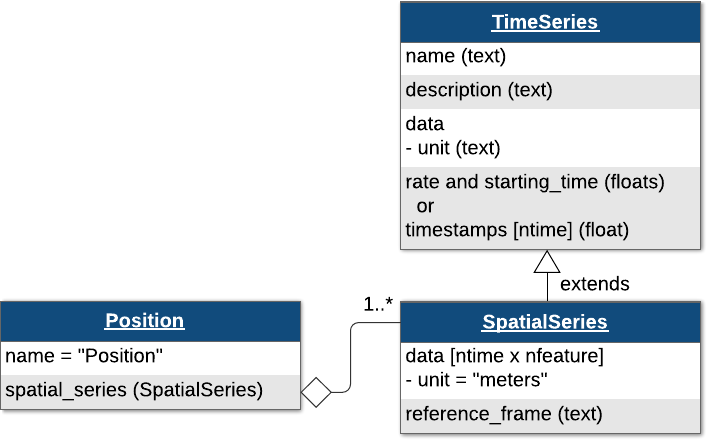 

Here, we put a `SpatialSeries` object called `'SpatialSeries'` in a `Position` object, and put that in a  `ProcessingModule` named `'behavior'`.

position_data = [linspace(0,10,100); linspace(0,8,100)]';

spatial_series_ts = types.core.SpatialSeries( ...
    'data', position_data, ...
    'reference_frame', '(0,0) is bottom left corner', ...
    'timestamps', linspace(0, 100)/200)

spatial_series_ts =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
               comments: 'no comments'
                control: []
    control_description: []
                   data: [100×2 double]
        data_continuity: []
        data_conversion: 1
        data_resolution: -1
              data_unit: 'meters'
            description: 'no description'
          starting_time: []
     starting_time_rate: []
             timestamps: [1×100 double]


To help data analysis and visualization tools know that this `SpatialSeries` object represents the position of the animal, store the `SpatialSeries` object inside of a `Position` object.

Position = types.core.Position('SpatialSeries', spatial_series_ts);

NWB differentiates between raw, *acquired data*, which should never change, and *processed data*, which are the results of preprocessing algorithms and could change. Let's assume that the animal's position was computed from a video tracking algorithm, so it would be classified as processed data. Since processed data can be very diverse, NWB allows us to create processing modules, which are like folders, to store related processed data or data that comes from a single algorithm.

Create a processing module called "behavior" for storing behavioral data in the `NWBFile` and add the `Position` object to the module.

% create processing module
behavior_mod = types.core.ProcessingModule( ...
    'description',  'contains behavioral data')

behavior_mod =   ProcessingModule with properties:

         description: 'contains behavioral data'
        dynamictable: [0×1 types.untyped.Set]
    nwbdatainterface: [0×1 types.untyped.Set]



% add the Position object (that holds the SpatialSeries object)
behavior_mod.nwbdatainterface.set(...
    'Position', Position);

% add the processing module to the NWBFile object, and name it "behavior"
nwb.processing.set('behavior', behavior_mod);

### Test write

Now, write the NWB file that we have built so far.

nwbExport(nwb, 'ophys_tutorial1.nwb')

We can then read the file and print it to inspect its contents. We can also print the `SpatialSeries` data that we created by referencing the names of the objects in the hierarchy that contain it. The processing module called `'behavior'` contains our `Position` object. By default, the `Position` object is named `'Position'`. The `Position` object contains our `SpatialSeries` object named `'SpatialSeries'`.

read_nwbfile = nwbRead('ophys_tutorial1.nwb')

read_nwbfile =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                        file_create_date: [1×1 types.untyped.DataStub]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
                          general_experiment_description: []
                                    general_experimenter: [1×1 types.untyped.DataStub]
                             general_extracellular_ephys: [0×1 types.untyped.Set]
                  general_extracellular_ephys_electrodes: []
                                     general_institution: 'U

read_nwbfile.processing.get('behavior').nwbdatainterface.get('Position').spatialseries.get('SpatialSeries')

ans =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
               comments: 'no comments'
                control: []
    control_description: []
                   data: [1×1 types.untyped.DataStub]
        data_continuity: []
        data_conversion: 1
        data_resolution: -1
              data_unit: 'meters'
            description: 'no description'
          starting_time: []
     starting_time_rate: []
             timestamps: [1×1 types.untyped.DataStub]


We can also use the [HDFView](https://www.hdfgroup.org/downloads/hdfview/) tool to inspect the resulting NWB file.

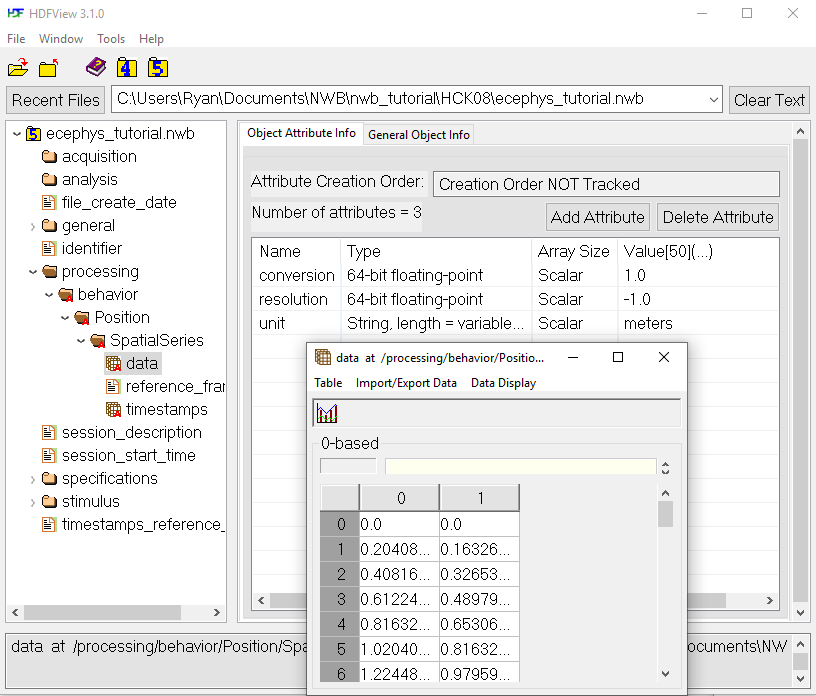

### Trials

Trials are stored in a `TimeIntervals` object which is a subclass of `DynamicTable`. `DynamicTable` objects are used to store tabular metadata throughout NWB, including for trials, electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns.

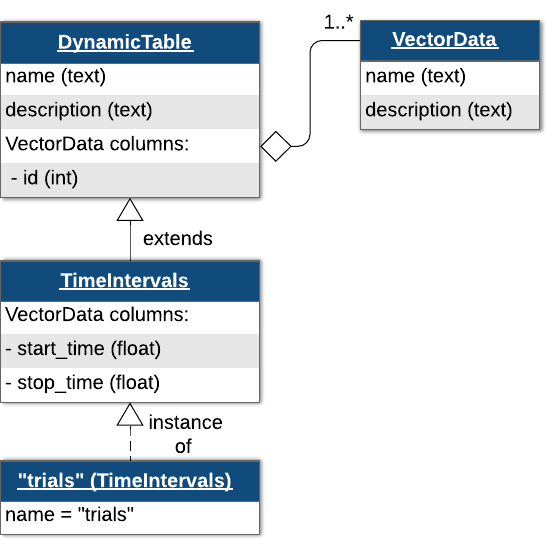

The trials `DynamicTable` can be thought of as a table with this structure:

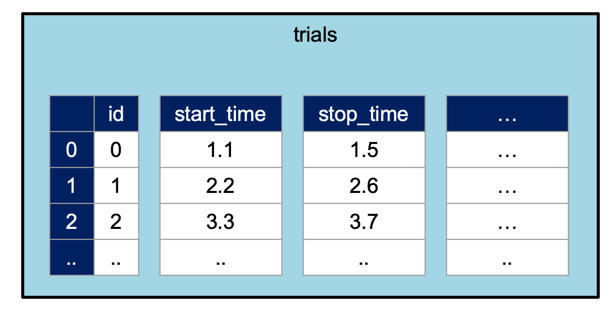

Trials are stored in a `TimeInterval` object which subclasses `DynamicTable`. Here, we are adding `'correct'`, which will be a `boolean` array.

trials = types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'correct'}, ...
    'description', 'trial data and properties', ...
    'id', types.hdmf_common.ElementIdentifiers('data', 0:2), ...
    'start_time', types.hdmf_common.VectorData('data', [.1, 1.5, 2.5], ...
   	'description','start time of trial'), ...
    'stop_time', types.hdmf_common.VectorData('data', [1., 2., 3.], ...
   	'description','end of each trial'), ...
    'correct', types.hdmf_common.VectorData('data', [false, true, false], ...
   	'description', 'whether the trial was correct'))

trials =   TimeIntervals with properties:

          start_time: [1×1 types.hdmf_common.VectorData]
           stop_time: [1×1 types.hdmf_common.VectorData]
                tags: []
          tags_index: []
          timeseries: []
    timeseries_index: []
            colnames: {'start_time'  'stop_time'  'correct'}
         description: 'trial data and properties'
                  id: [1×1 types.hdmf_common.ElementIdentifiers]
          vectordata: [1×1 types.untyped.Set]


nwb.intervals_trials = trials;

## Optical Physiology

Optical physiology results are written in four steps:

- Create imaging plane

- Acquired two-photon images

- Image segmentation

- Fluorescence and dF/F responses

### Imaging Plane

First, you must create an `ImagingPlane` object, which will hold information about the area and method used to collect the optical imaging data. This requires creation of a `Device` object for the microscope and an `OpticalChannel` object. Then you can create an `ImagingPlane`.

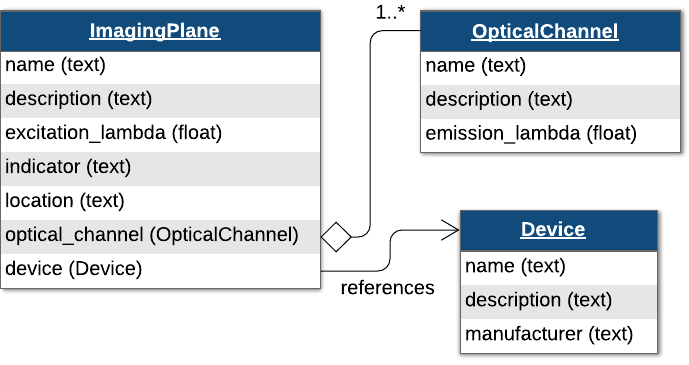

optical_channel = types.core.OpticalChannel( ...
    'description', 'description', ...
    'emission_lambda', 500.);

device = types.core.Device();
nwb.general_devices.set('Device', device);

imaging_plane_name = 'imaging_plane';
imaging_plane = types.core.ImagingPlane( ...
    'optical_channel', optical_channel, ...
    'description', 'a very interesting part of the brain', ...
    'device', types.untyped.SoftLink(device), ...
    'excitation_lambda', 600., ...
    'imaging_rate', 5., ...
    'indicator', 'GFP', ...
    'location', 'my favorite brain location');

nwb.general_optophysiology.set(imaging_plane_name, imaging_plane);

### Storing raw optical physiology data

Now that you have your `ImagingPlane`, you can create a `TwoPhotonSeries` the class representing two photon imaging data. `TwoPhotonSeries`, like `SpatialSeries`, inherits from `TimeSeries`.

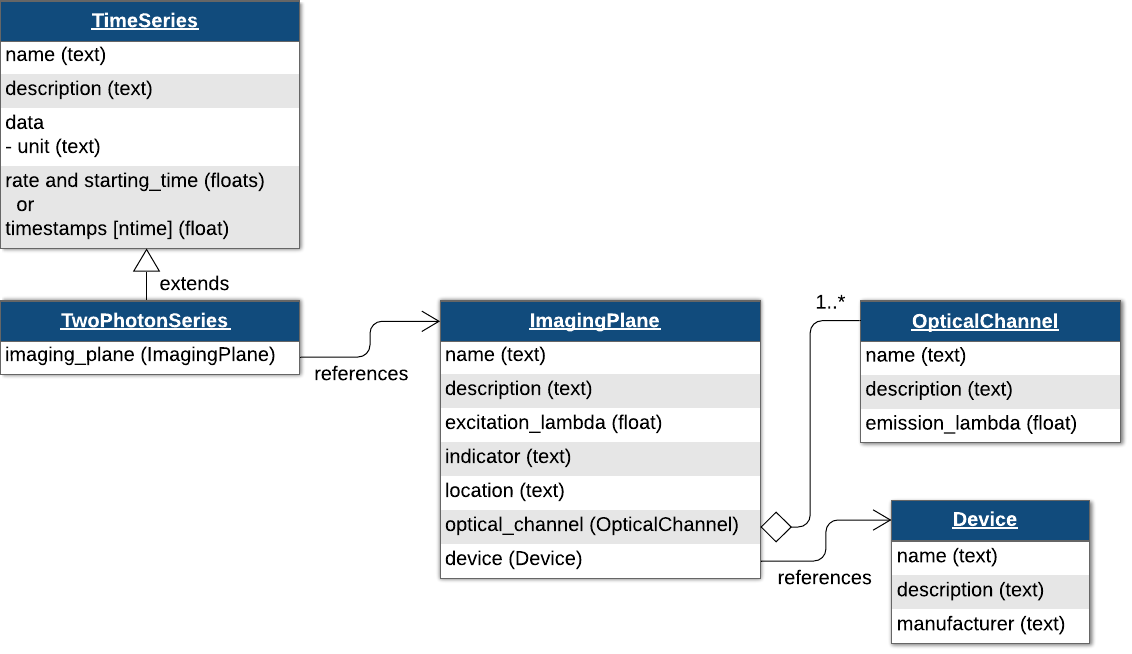

From here you have two options. The first option is to supply the image data using the `data` argument. The other option is the provide a path the images. These two options have trade-offs, so it is worth spending time considering how you want to store this data.

#### Adding the data directly to the NWBFile

image_series = types.core.TwoPhotonSeries( ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'starting_time', 0.0, ...
    'starting_time_rate', 3.0, ...
    'data', ones(200, 100, 1000), ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries', image_series);

#### Linking externally to the data

image_series = types.core.TwoPhotonSeries( ...
    'external_file', 'images.tiff', ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'external_file_starting_frame', 0, ...
    'format', 'tiff', ...
    'starting_time_rate', 3.0, ...
    'starting_time', 0.0, ...
    'data', NaN(2, 2, 2), ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries2', image_series);

### Plane Segmentation

Image segmentation stores the detected regions of interest in the `TwoPhotonSeries` data. `ImageSegmentation` allows you to have more than one segmentation by creating more `PlaneSegmentation` objects.

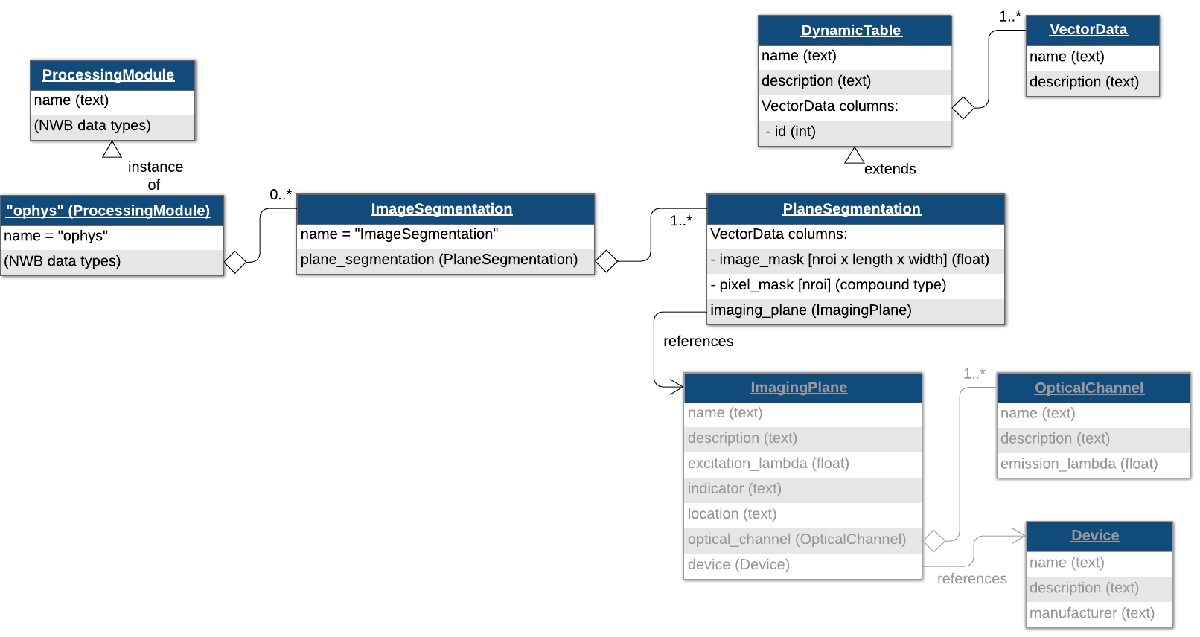

### Regions of interest (ROIs)

Add ROIs using an image mask. An image mask is an array that is the same size as a single frame of the `TwoPhotonSeries`, and indicates where a single region of interest is. This image mask may be boolean or continuous between 0 and 1.

% generate fake image_mask data
imaging_shape = [100, 100];
x = imaging_shape(1);
y = imaging_shape(2);

n_rois = 20;
image_mask = zeros(y, x, n_rois);
for i = 1:n_rois
    start = randi(90,2,1);
    image_mask(start(1):start(1)+10, start(2):start(2)+10, 1) = 1;
end

% add data to NWB structures
plane_segmentation = types.core.PlaneSegmentation( ...
    'colnames', {'image_mask'}, ...
    'description', 'output from segmenting my favorite imaging plane', ...
    'id', types.hdmf_common.ElementIdentifiers('data', int64(0:19)), ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane));

plane_segmentation.image_mask = types.hdmf_common.VectorData( ...
    'data', image_mask, 'description', 'image masks');

Now create an `ImageSegmentation` object and put the `plane_segmentation` object inside of it, naming it `PlaneSegmentation`.

img_seg = types.core.ImageSegmentation();
img_seg.planesegmentation.set('PlaneSegmentation', plane_segmentation)

ans =   Set with properties:

    PlaneSegmentation: [types.core.PlaneSegmentation]


Now create a `ProcessingModule` called "ophys" and put our `img_seg` object in it, calling it `ImageSegmentation`, and add the `ProcessingModule` to `nwb.`

ophys_module = types.core.ProcessingModule( ...
    'description',  'contains optical physiology data')

ophys_module =   ProcessingModule with properties:

         description: 'contains optical physiology data'
        dynamictable: [0×1 types.untyped.Set]
    nwbdatainterface: [0×1 types.untyped.Set]


ophys_module.nwbdatainterface.set('ImageSegmentation', img_seg);
nwb.processing.set('ophys', ophys_module);

### Storing fluorescence of ROIs over time

Now that ROIs are stored, you can store fluorescence dF/F data for these regions of interest. This type of data is stored using the `RoiResponseSeries` class. You will not need to instantiate this class directly to create objects of this type, but it is worth noting that this is the class you will work with after you read data back in.

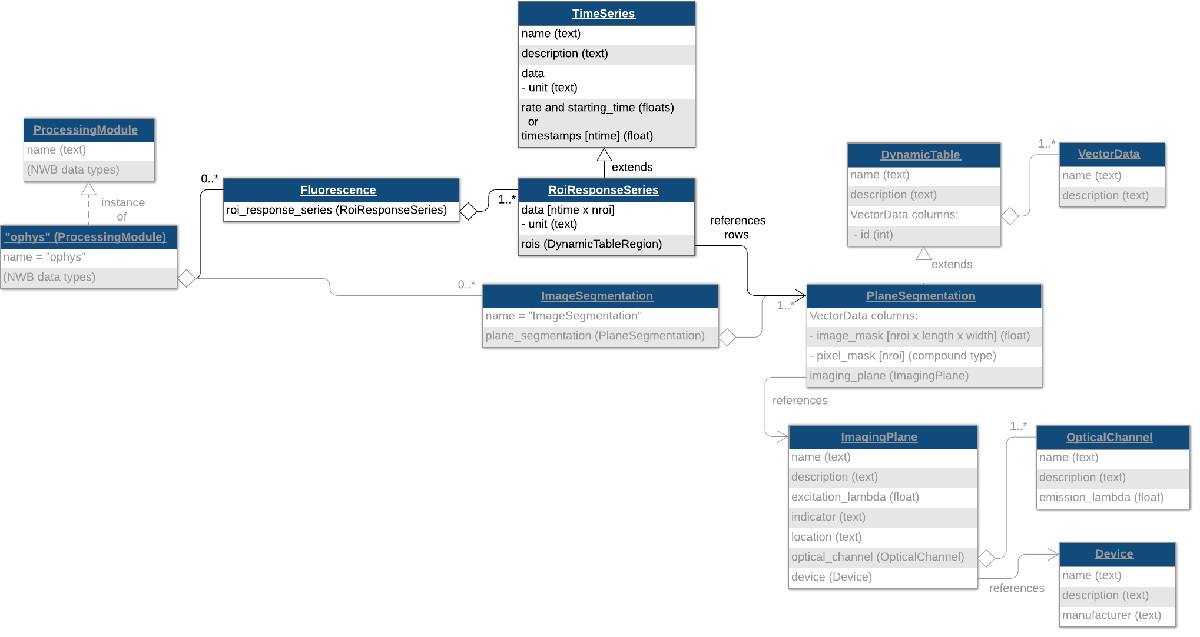

First, create a data interface to store this data in

roi_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(plane_segmentation), ...
    'description', 'all_rois', ...
    'data', [0 n_rois-1]');

roi_response_series = types.core.RoiResponseSeries( ...
    'rois', roi_table_region, ...
    'data', NaN(n_rois, 100), ...
    'data_unit', 'lumens', ...
    'starting_time_rate', 3.0, ...
    'starting_time', 0.0);

fluorescence = types.core.Fluorescence();
fluorescence.roiresponseseries.set('RoiResponseSeries', roi_response_series);

ophys_module.nwbdatainterface.set('Fluorescence', fluorescence);

Finally, the ophys `ProcessingModule` is added to the `NwbFile`.

nwb.processing.set('ophys', ophys_module);

Write the NWB file

nwbExport(nwb, 'ophys_tutorial.nwb');

## Reading the NWB file

read_nwb = nwbRead('ophys_tutorial.nwb');

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. 

read_nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence')...
    .roiresponseseries.get('RoiResponseSeries').data

ans =   DataStub with properties:

    filename: 'ophys_tutorial.nwb'
        path: '/processing/ophys/Fluorescence/RoiResponseSeries/data'
        dims: [20 100]
       ndims: 2


This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access the data in the matrix using the `load` method. 

`load` with no input arguments reads the entire dataset:


read_nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence'). ...
    roiresponseseries.get('RoiResponseSeries').data.load

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

If all you need is a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB. This will just read the selected region from disk into RAM. This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM.

read_nwb.processing.get('ophys'). ...
    nwbdatainterface.get('Fluorescence'). ...
    roiresponseseries.get('RoiResponseSeries'). ...
    data(1:5, 1:10)

ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


% read back the image masks
read_nwb.processing.get('ophys'). ...
    nwbdatainterface.get('ImageSegmentation'). ...
    planesegmentation.get('PlaneSegmentation'). ...
    image_mask.data.load

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## Other MatNWB tutorials

- [Extracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ecephys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)